% 3.23a
s = tf("s")

s =
 
  s
 
Continuous-time transfer function.




G = 0.2/((s^2+s+1)*(s + 0.2))

G =
 
              0.2
  ---------------------------
  s^3 + 1.2 s^2 + 1.2 s + 0.2
 
Continuous-time transfer function.



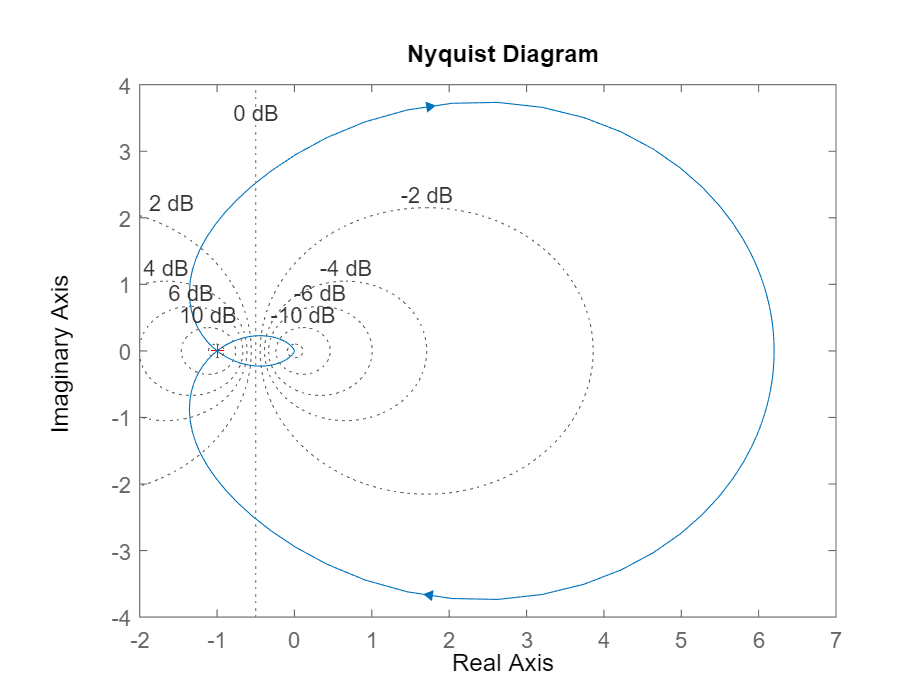

Kp = 6.2;
F = Kp;

nyquist(F*G)
grid


%Asymtotically instable when Kp>6.2, semi-unstable when Kp = 6.2


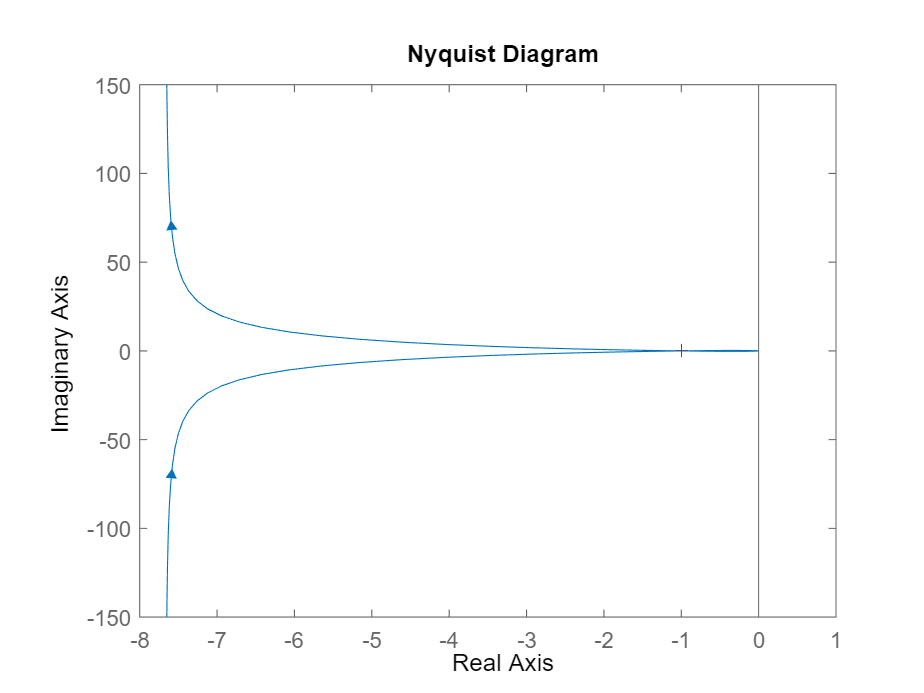

% 3.23b
Kp1 = 1;
Ki = 1.4444445;
F1 = Kp1+Ki/s;
figure
nyquist(F1*G)

Gb = feedback(F1*G, 1)

Gb =
 
               0.2 s + 0.2889
  ----------------------------------------
  s^4 + 1.2 s^3 + 1.2 s^2 + 0.4 s + 0.2889
 
Continuous-time transfer function.



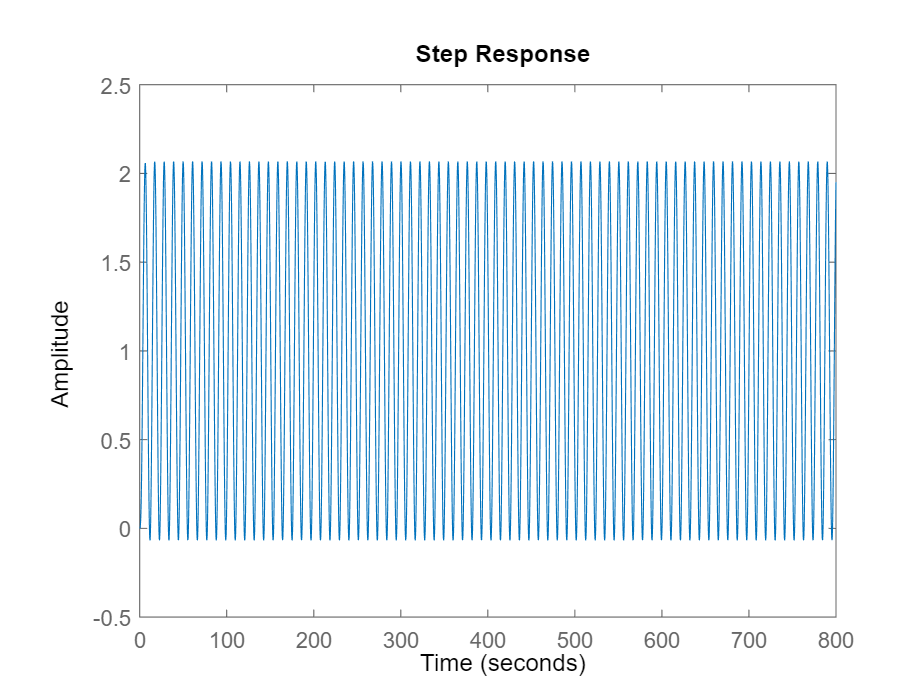

step(Gb)

% semi 1.44444444
% instsblr when >= 1.4444445


%3.23c
Kp2 = 1;
Ki2 = 1;
Kd2 = 65.9707;

TD=0.1;

F2=Kp2+(Ki2/s)+(Kd2*s)/(s*TD+1)

F2 =
 
  66.07 s^2 + 1.1 s + 1
  ---------------------
       0.1 s^2 + s
 
Continuous-time transfer function.




Gc = feedback(F2*G, 1)

Gc =
 
                  13.21 s^2 + 0.22 s + 0.2
  --------------------------------------------------------
  0.1 s^5 + 1.12 s^4 + 1.32 s^3 + 14.43 s^2 + 0.42 s + 0.2
 
Continuous-time transfer function.



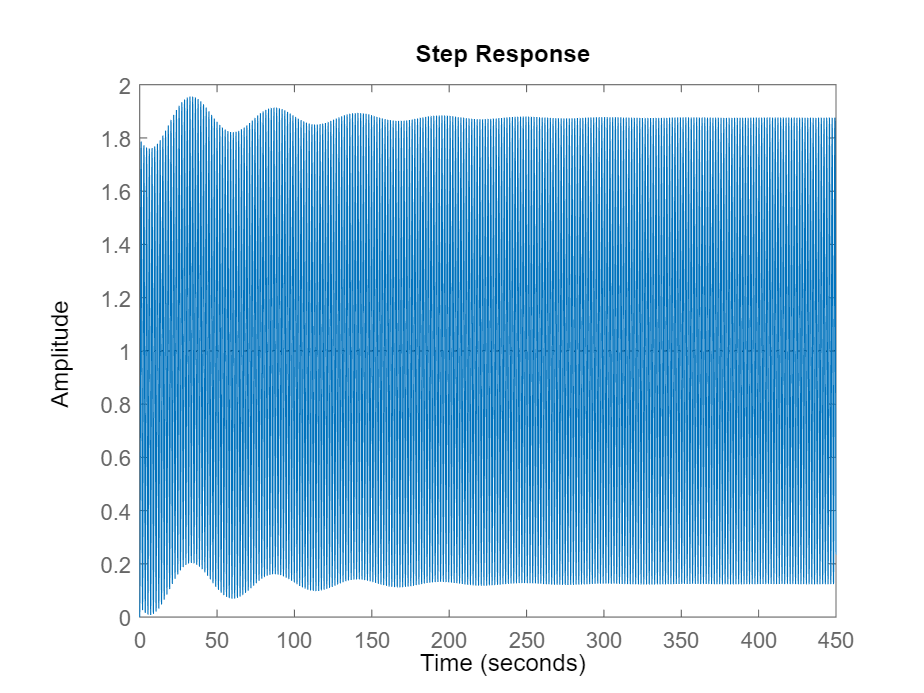

step(Gc)

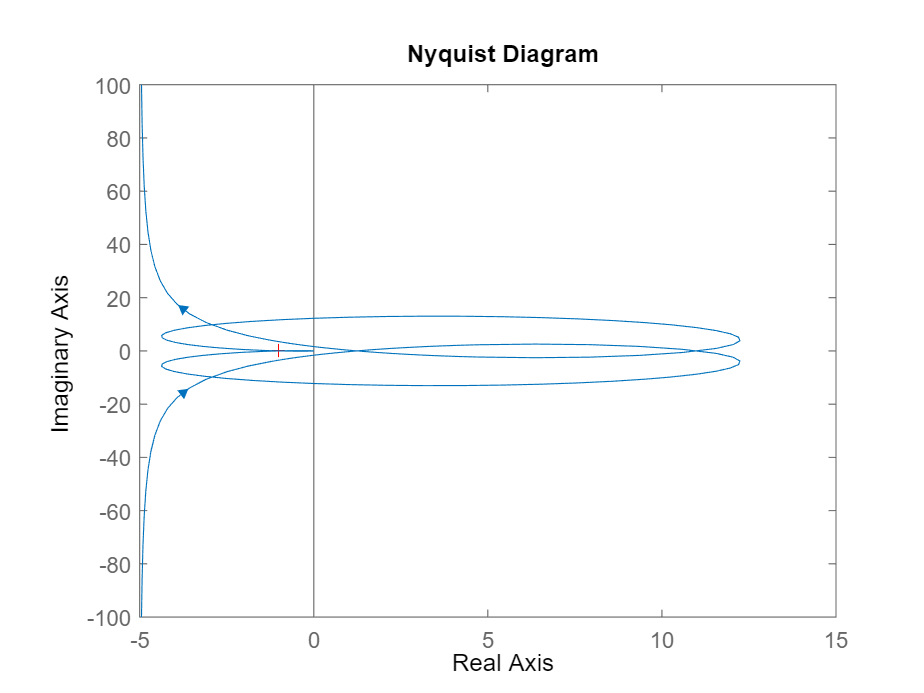


figure
nyquist(F2*G)


%semi at Kd = 65.9707
% unstable when Kd > 65.9707

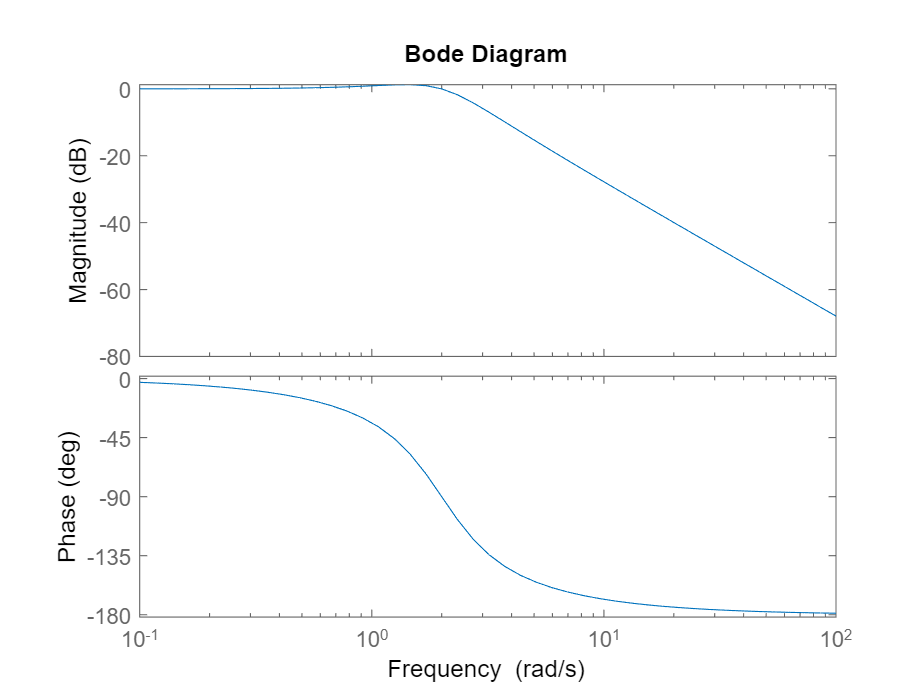

%4.5

Ga=1/(s^2+2*s+1);
Gb=1/(s^2+0.4*s+1);
Gc=1/(s^2+5*s+1);
Gd=1/(s^2+s+1);
Ge=4/(s^2+2*s+4);

%bode(Ga)
%step(feedback(Ga, 1))
% Tr = 1.52, wB = 0.641189, M = 4.32%, Mp missing

%bode(Gb)
%step(feedback(Gb, 1))
% Tr = 0.825, wB = 1.5108, M = 63.8%, Mp = 8.14

%bode(Gc)
%step(feedback(Gc, 1))
%Tr = 5.05, wB = 0.2072, M = 0%, Mp missing

%bode(Gd)
%step(feedback(Gd, 1))
%Tr = 0.989, wB = 1.2653, M = 30.5%, Mp = 1.24

bode(Ge)

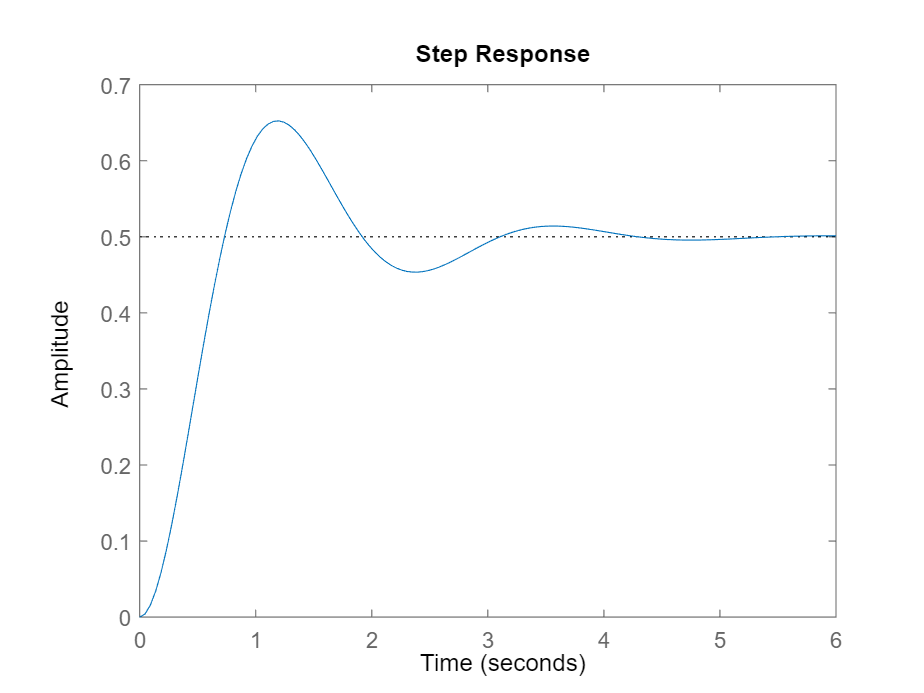

step(feedback(Ge, 1))

%Tr = 0.494, wB = 2.5375, M = 30.5%, Mp = 1.24

%b Tr is inversly preportional to wB, M and Mp are similar and approx. proportional


%3.24a

G2 = 0.4/((s^2+s+1)*(s+0.2))

G2 =
 
                
             0.4
                
  --------------------------
                            
  s^3 + 1.2 s^2 + 1.2 s     
                            
                       + 0.2
                            
 
Continuous-time transfer function.



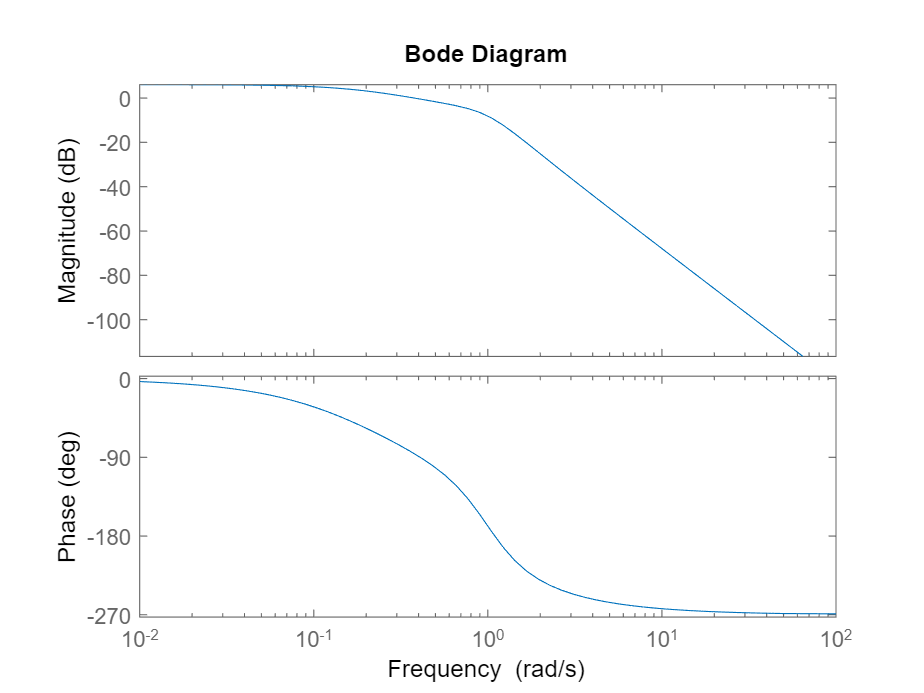


Kp3 = 1;
F3 = Kp3;

bode(F3*G2)


$$\begin{array}{l}
\phi m=94\ldotp 2\\
\omega c=0\ldotp 375\;\mathrm{rad}\;\mathrm{per}\;s\\
\omega p=1\ldotp 1\;\mathrm{rad}\;\mathrm{per}\;s\\
\mathrm{Am}=9\ldotp 83
\end{array}$$


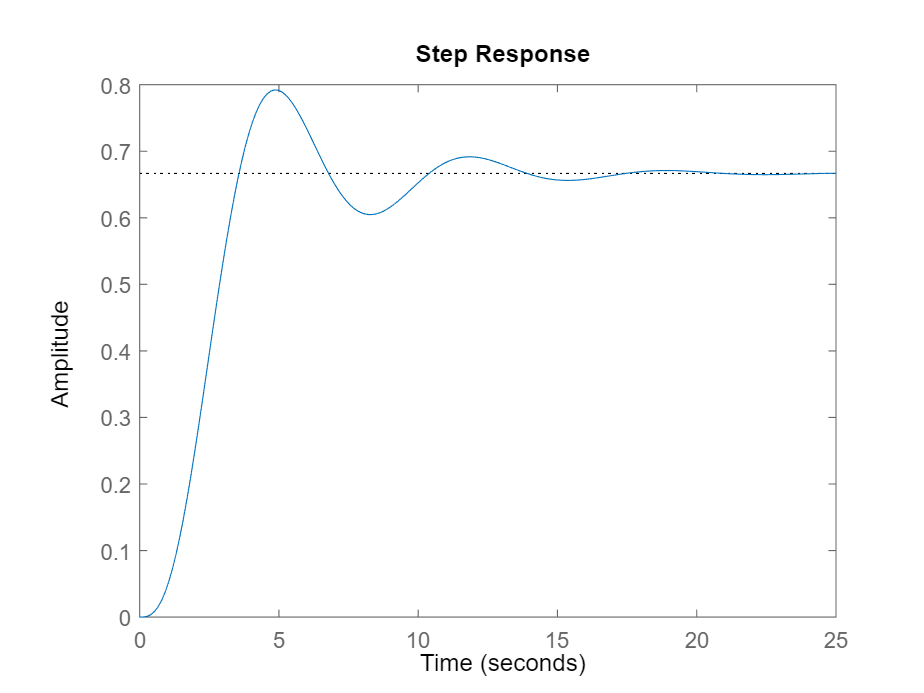


step(feedback(F3*G2, 1))

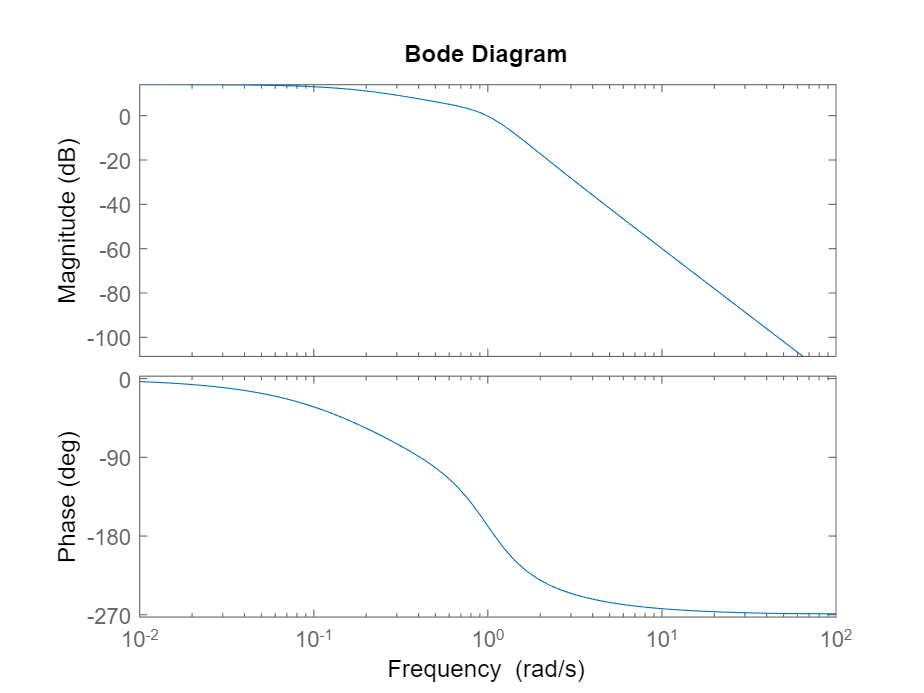

%3.24b

Kp4 = 2.5;
F4 = Kp4;

bode(F4*G2)


$$\begin{array}{l}
\phi m=12\ldotp 6\\
\omega c=0\ldotp 984\;\mathrm{rad}\;\mathrm{per}\;s\\
\omega p=1\ldotp 09\;\mathrm{rad}\;\mathrm{per}\;s\\
\mathrm{Am}=1\ldotp 87
\end{array}$$


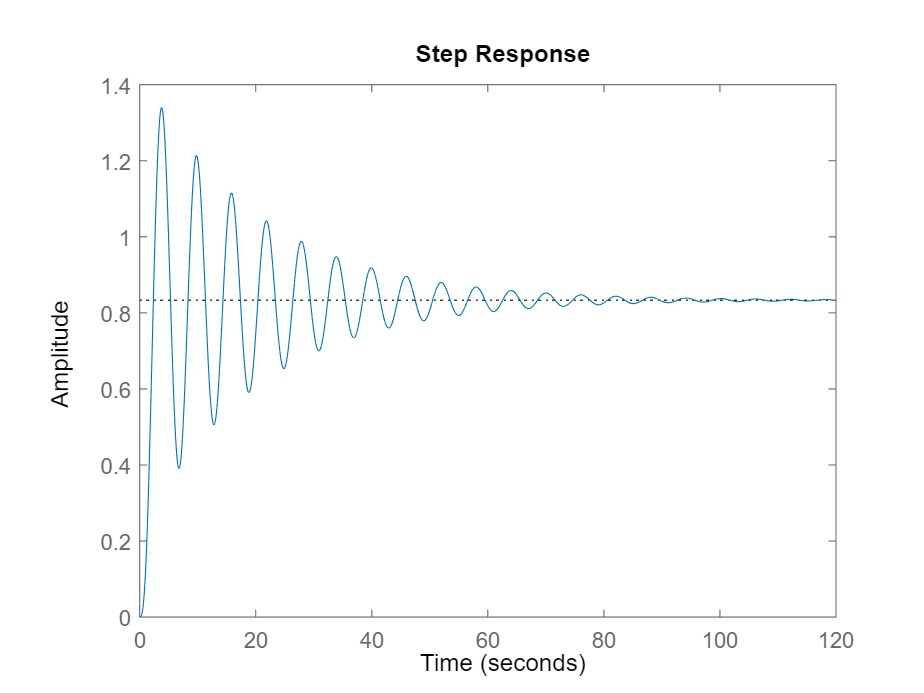

step(feedback(F4*G2, 1))

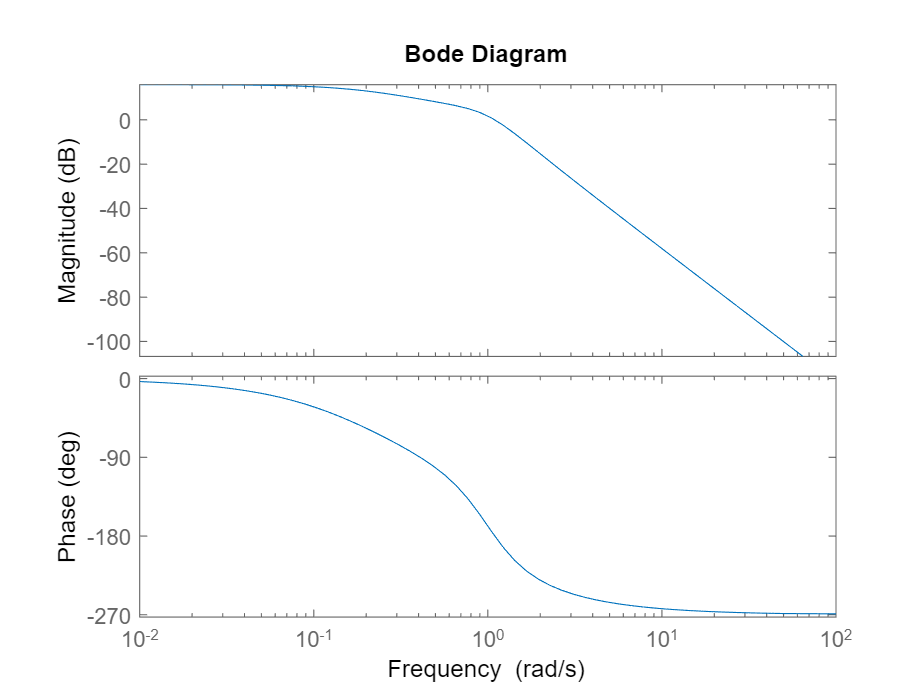

%3.24b

Kp5 = 3.1;
F5 = Kp5;

bode(F5*G2)


$$\begin{array}{l}
\phi m=0\\
\omega c=1\ldotp 1\;\mathrm{rad}\;\mathrm{per}\;s\\
\omega p=1\ldotp 1\;\mathrm{rad}\;\mathrm{per}\;s\\
\mathrm{Am}=0
\end{array}$$


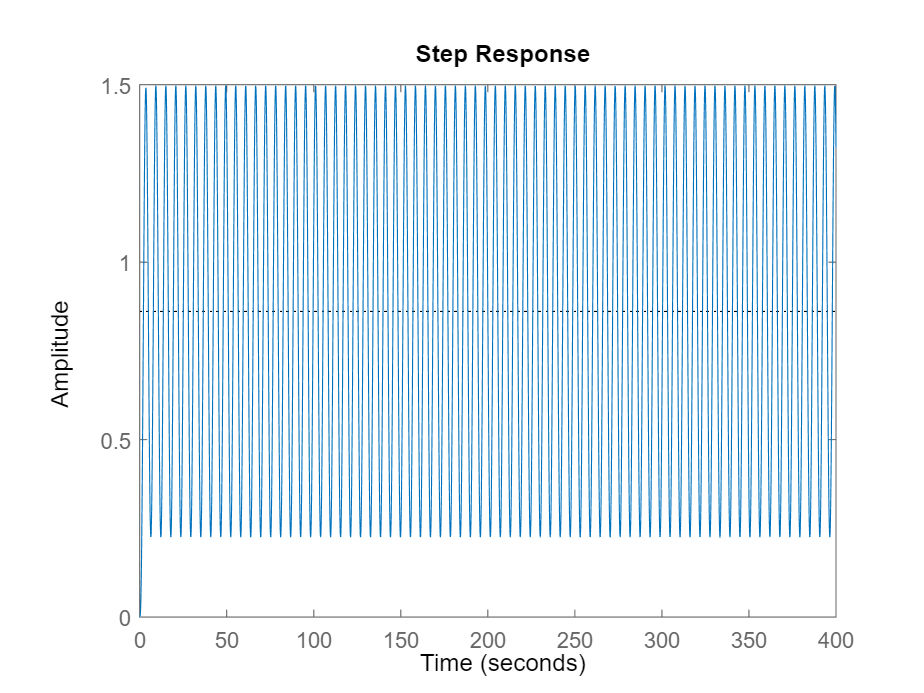

step(feedback(F5*G2, 1))

%Kp5 = 3.1 unstable



figure
%h = bodeplot(G, {0.01, 100});
%setoptions(h, "MagUnits", "dB", "MagScale", "linear", "PhaseVisable", "off");
%grid

